# **Local Auxiliary Functions Verification**

clear all; clc; close all;
clear functions;

**AuxFcn_ReadDAQ_TXT_000**

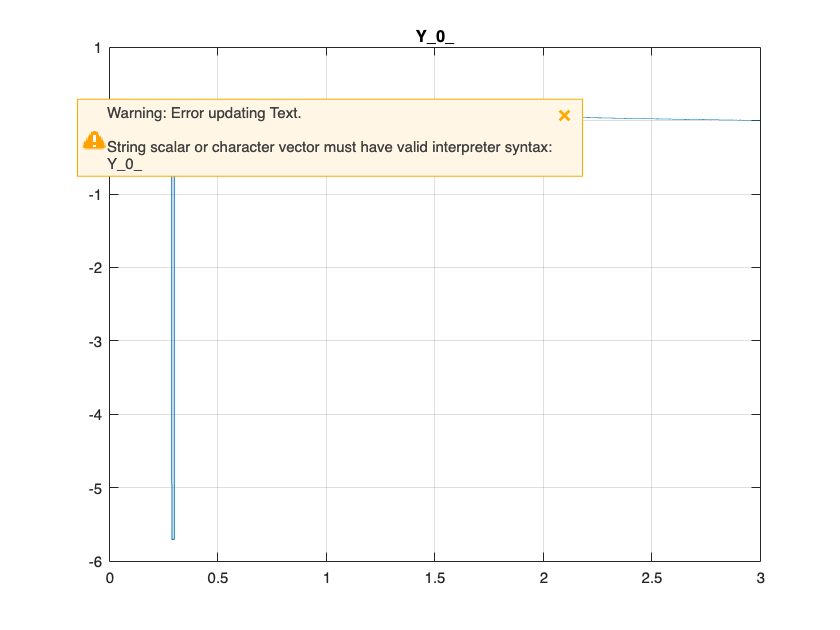

  % Basic read (uses header dt to construct uniform t)
  daq1 = AuxFcn_ReadDAQ_TXT_001('Problem grounding.txt', 'DaqId',"DAQ1");
  plot(daq1.t, daq1.signal(:,1)); grid on;
  title(char(daq1.channelNames(1)), 'Interpreter','latex');

**AuxFcn_ReadTPC5_000**

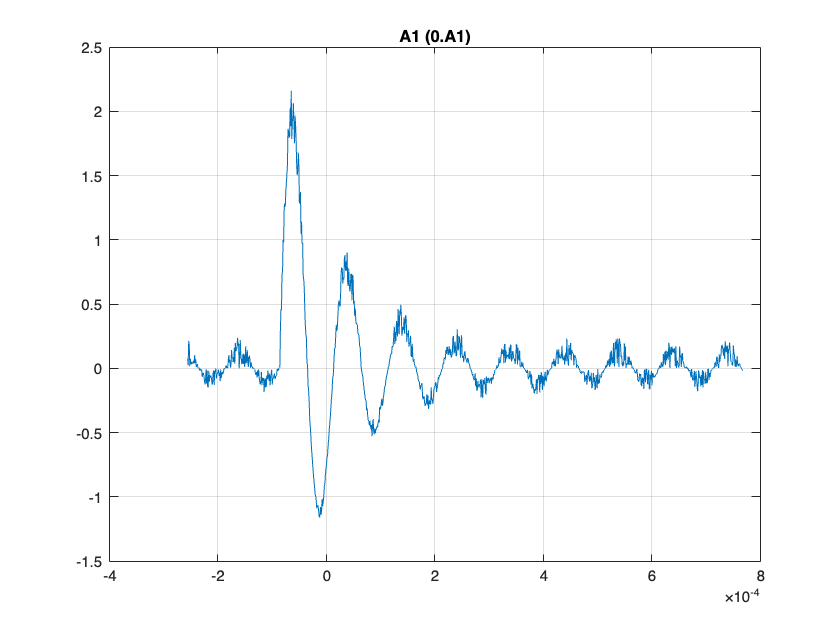

  daq2 = AuxFcn_ReadTPC5_001('mytrace.tpc5', 'DaqId',"DAQ2");
  plot(daq2.t, daq2.signal(:,1)); grid on;
  title(char(daq2.channelNames(1)), 'Interpreter','none');

**AuxFcn_LoadExperiment_000**

cfg = struct();
cfg.daq1_txt_files  = {'Problem grounding.txt','Test 2.txt','test 3.txt'};
cfg.daq2_tpc5_files = {'mytrace.tpc5','mytrace.tpc5','SmallPump.tpc5'};
cfg.daq1_id = "DAQ1";
cfg.daq2_id = "DAQ2";
% Optional: units for DAQ1 (since TXT doesn't include them)
cfg.daq1_units = ["bar","bar","bar","bar"];
cfg.daq1_channelType = ["pressure","pressure","pressure","pressure"];

% Optional: type for DAQ2
% cfg.daq2_trigger_channelIdx = 4;  % example: A4 is trigger
cfg.daq2_trigger_channelIdx = [4 4 NaN];  % NaN when no trigger present in that file
cfg.daq2_trigger_namePattern = "trig|trigger|ttl|ign";

tests  = AuxFcn_LoadExperiment_000(cfg);

#### A) Plot directly from `AuxFcn_LoadExperiment_000` output (`tests`)

1) Inspect

i = 1;

% See what fields exist
% DAQ1
fieldnames(tests(i))

ans = 3×1 cell array
    {'DAQ1'}
    {'DAQ2'}
    {'meta'}


fieldnames(tests(i).DAQ1)

ans = 14×1 cell array
    {'name'        }
    {'file'        }
    {'daqId'       }
    {'dt'          }
    {'fs'          }
    {'tbl'         }
    {'t'           }
    {'signal'      }
    {'nSamples'    }
    {'nChannels'   }
    {'channelNames'}
    {'units'       }
    {'channelType' }
    {'meta'        }


tests(i).DAQ1.name

ans = "Problem grounding.txt"

tests(i).DAQ1.fs

ans =    208.3330e+003


% DAQ2
fieldnames(tests(i).DAQ2)

ans = 13×1 cell array
    {'name'        }
    {'file'        }
    {'daqId'       }
    {'dt'          }
    {'fs'          }
    {'t'           }
    {'signal'      }
    {'nSamples'    }
    {'nChannels'   }
    {'channelNames'}
    {'units'       }
    {'meta'        }
    {'channelType' }


tests(i).DAQ2.name

ans = "mytrace.tpc5"

tests(i).DAQ2.fs

ans =      1.0000e+006



% Check channel names and units
tests(i).DAQ1.channelNames

ans = 1×4 string array
    "Y_0_"    "Y_1_"    "Y_2_"    "Y_3_"


tests(i).DAQ1.units

ans = 1×4 string array
    "bar"    "bar"    "bar"    "bar"



tests(i).DAQ2.channelNames

ans = 1×4 string array
    "A1 (0.A1)"    "A2 (0.A2)"    "A3 (0.A3)"    "A4 (0.A4)"


tests(i).DAQ2.units

ans = 1×4 string array
    "V"    "V"    "V"    "V"


2) Plot one channel (DAQ1)

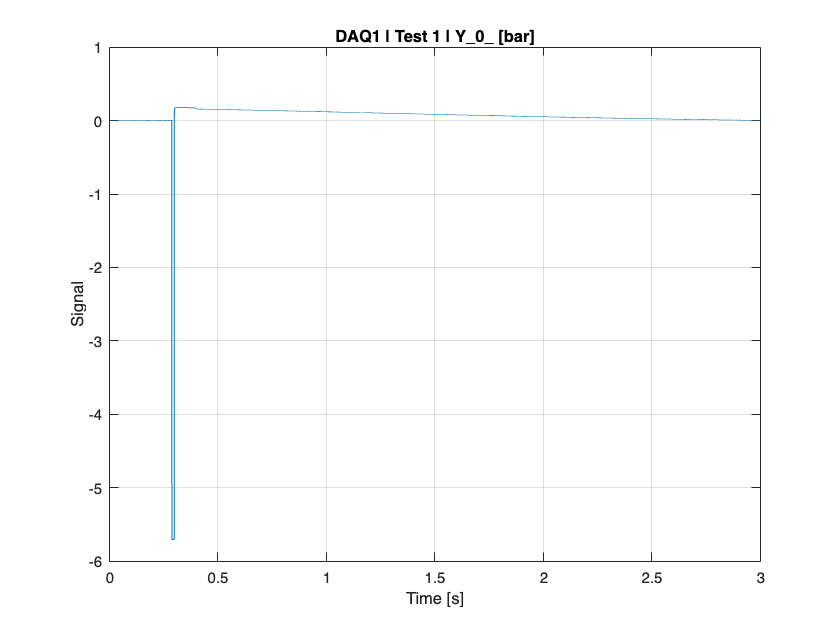

i = 1;          % test index
ch = 1;         % channel index (1..DAQ1.nChannels)

t = tests(i).DAQ1.t;
y = tests(i).DAQ1.signal(:, ch);

figure;
plot(t, y); grid on;
title(sprintf('DAQ1 | Test %d | %s [%s]', i, ...
    char(tests(i).DAQ1.channelNames(ch)), char(tests(i).DAQ1.units(ch))), ...
    'Interpreter','none');
xlabel('Time [s]'); ylabel('Signal');

3) Plot all channels for DAQ1 (stacked subplots)

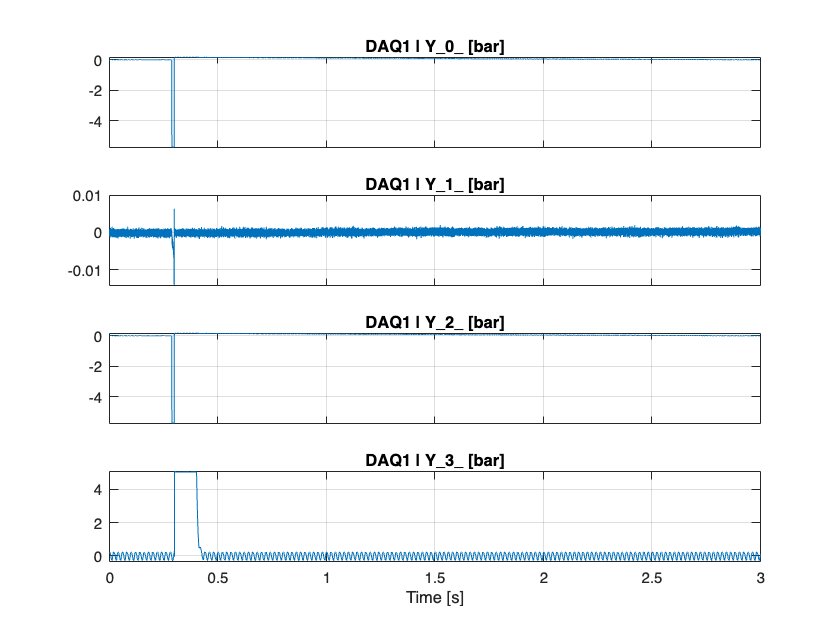

i = 1;

t = tests(i).DAQ1.t;
Y = tests(i).DAQ1.signal;
nC = tests(i).DAQ1.nChannels;

figure;
for ch = 1:nC
    subplot(nC,1,ch);
    plot(t, Y(:,ch)); grid on;
    title(sprintf('DAQ1 | %s [%s]', ...
        char(tests(i).DAQ1.channelNames(ch)), char(tests(i).DAQ1.units(ch))), ...
        'Interpreter','none');
    if ch < nC, set(gca,'XTickLabel',[]); else, xlabel('Time [s]'); end
end

4) Compare DAQ1 vs DAQ2 for the “same” sensor index (no merge)

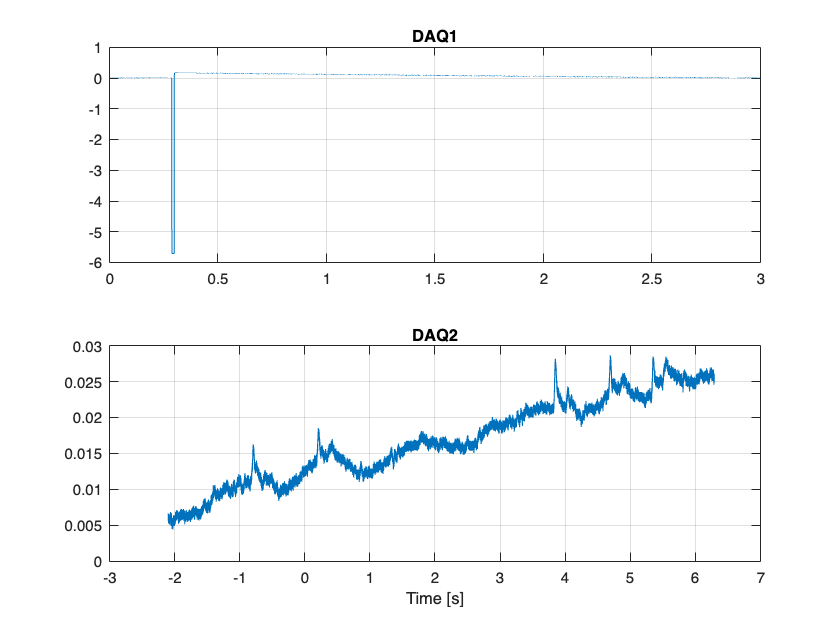

i = 1;
chDAQ1 = 1;


figure;
subplot(2,1,1);
plot(tests(i).DAQ1.t, tests(i).DAQ1.signal(:,chDAQ1)); grid on;
title('DAQ1', 'Interpreter','none');

i = 3;
chDAQ2 = 1;
subplot(2,1,2);
plot(tests(i).DAQ2.t, tests(i).DAQ2.signal(:,chDAQ2)); grid on;
title('DAQ2', 'Interpreter','none');
xlabel('Time [s]');

#### B) Plot from `AuxFcn_BuildTensorFromTests_000` output (tensor)

outDAQ1 = AuxFcn_BuildTensorFromTests_000(tests, "DAQ1");
outDAQ2 = AuxFcn_BuildTensorFromTests_000(tests, "DAQ2");

1) Plot one channel from a tensor (DAQ1)

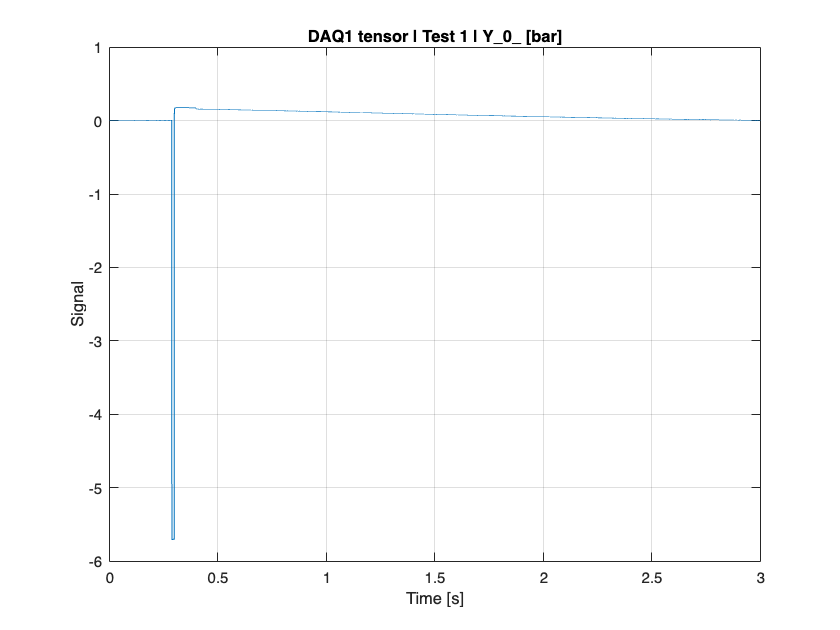

i = 1;
ch = 1;                      % channel number 1..validNChannels_DAQ1(i)
nS = outDAQ1.validNSamples(i);

t = squeeze(outDAQ1.testSignalTensor(i,1,1:nS)).';
y = squeeze(outDAQ1.testSignalTensor(i,1+ch,1:nS)).';

figure;
plot(t, y); grid on;

% Use real channel name/unit stored per test
chName = outDAQ1.channelNamesByTest{i}(ch);
chUnit = outDAQ1.unitsByTest{i}(ch);
title(sprintf('DAQ1 tensor | Test %d | %s [%s]', i, char(chName), char(chUnit)), ...
    'Interpreter','none');
xlabel('Time [s]'); ylabel('Signal');

2) Plot all channels from a tensor (DAQ2 example)

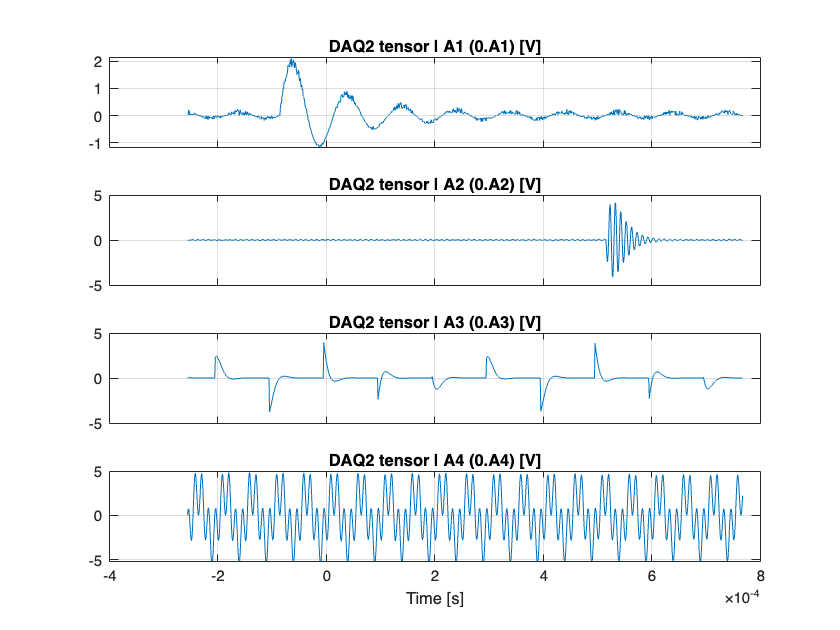

i = 1;
nS = outDAQ2.validNSamples(i);
nC = outDAQ2.validNChannels(i);

t = squeeze(outDAQ2.testSignalTensor(i,1,1:nS)).';
Y = squeeze(outDAQ2.testSignalTensor(i,2:(1+nC),1:nS)).';   % [nS x nC]

figure;
for ch = 1:nC
    subplot(nC,1,ch);
    plot(t, Y(:,ch)); grid on;

    chName = outDAQ2.channelNamesByTest{i}(ch);
    chUnit = outDAQ2.unitsByTest{i}(ch);
    title(sprintf('DAQ2 tensor | %s [%s]', char(chName), char(chUnit)), 'Interpreter','none');

    if ch < nC, set(gca,'XTickLabel',[]); else, xlabel('Time [s]'); end
end

#### C) Two quick “checks”

1) Verify per-test sampling rates (since you’re comparing DAQs)

for i = 1:numel(tests)
    if ~isempty(tests(i).DAQ1)
        fprintf('Test %d | DAQ1 Fs = %.3f Hz\n', i, tests(i).DAQ1.fs);
    end
    if ~isempty(tests(i).DAQ2)
        fprintf('Test %d | DAQ2 Fs = %.3f Hz\n', i, tests(i).DAQ2.fs);
    end
end

Test 1 | DAQ1 Fs = 208332.986 Hz


Test 1 | DAQ2 Fs = 1000000.000 Hz


Test 2 | DAQ1 Fs = 208332.986 Hz


Test 2 | DAQ2 Fs = 1000000.000 Hz


Test 3 | DAQ1 Fs = 208332.986 Hz


Test 3 | DAQ2 Fs = 1000000.000 Hz


2) Verify trigger channel detection on DAQ2 (TPC5)

i = 1;
if isfield(tests(i).DAQ2,'channelType')
    disp(table(tests(i).DAQ2.channelNames(:), tests(i).DAQ2.units(:), tests(i).DAQ2.channelType(:), ...
        'VariableNames', {'Channel','Unit','Type'}));
end

      Channel      Unit       Type   
    ___________    ____    __________

    "A1 (0.A1)"    "V"     "pressure"
    "A2 (0.A2)"    "V"     "pressure"
    "A3 (0.A3)"    "V"     "pressure"
    "A4 (0.A4)"    "V"     "trigger" 

